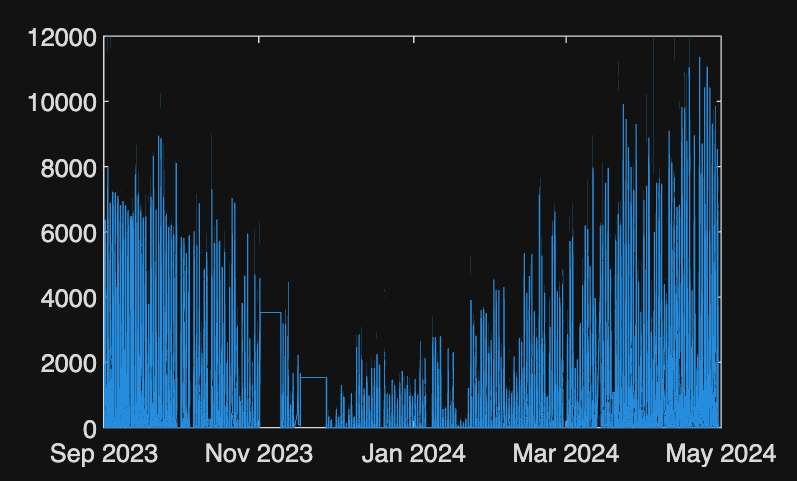

%Einteilung Datensätze Normalisierte Daten nehmen
D = readtimetable("cleanedData.txt");


%Ermittlung nicht verwertbarer Zeitabschnitte:
plot(D.timestamps, D.Q_sol)

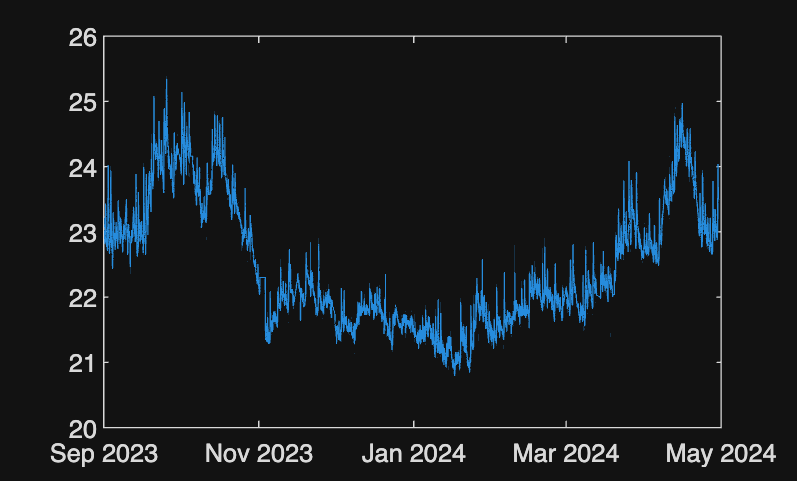

plot(D.timestamps,D.EG_Utilities_degC)

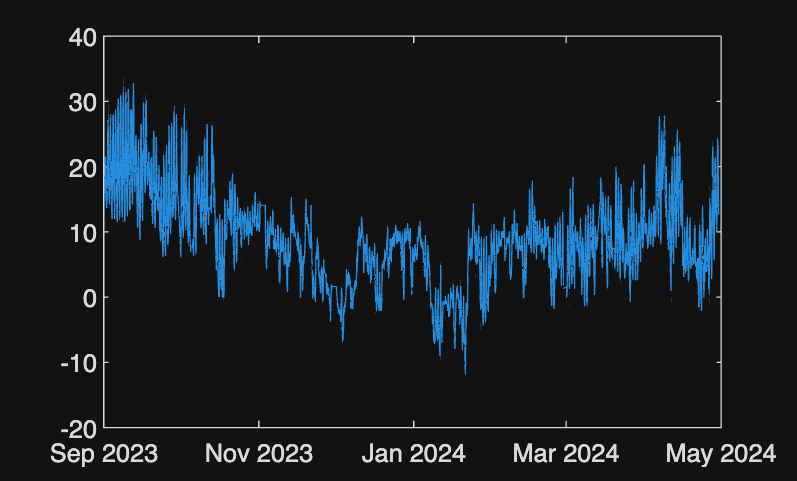

plot(D.timestamps,D.T_Amb_degC)



% -> Entfernung von 01.11 10:00-09.11 17:30 & 17.11 10:00 - 27.11 16:00
startTime = datetime('01-Nov-2023 10:00:00');
endTime = datetime('09-Nov-2023 17:30:00');
rowsToDelete = D.timestamps >= startTime & D.timestamps <= endTime;
D(rowsToDelete, :) = [];

startTime = datetime('17-Nov-2023 10:00:00');
endTime = datetime('27-Nov-2023 16:00:00');
rowsToDelete = D.timestamps >= startTime & D.timestamps <= endTime;
D(rowsToDelete, :) = [];

%Einteilung des Datensatzes periodisch in 2 Wochen Training, 1 Woche
%Validierung, 1 Woche Test
%Dafinition: Woche startet wie Datensatz -> hier 01.09.2023 00.15 und endet
%7 Tage später um 00:00
% Sampling in 15min Takt -> in diesem Beispiel 672 Zeilen pro Woche

%Training

sIv1 = datetime('01-Sep-2023 00:15:00');
eIv1 = datetime('15-Sep-2023 00:00:00');
sIv2 = datetime('29-Sep-2023 00:15:00');
eIv2 = datetime('13-Oct-2023 00:00:00');
sIv3 = datetime('27-Oct-2023 00:15:00');
eIv3 = datetime('01-Dec-2023 00:00:00');
sIv4 = datetime('15-Dec-2023 00:15:00');
eIv4 = datetime('29-Dec-2023 00:00:00');
sIv5 = datetime('12-Jan-2024 00:15:00');
eIv5 = datetime('26-Jan-2024 00:00:00');
sIv6 = datetime('09-Feb-2024 00:15:00');
eIv6 = datetime('23-Feb-2024 00:00:00');
sIv7 = datetime('08-Mar-2024 00:15:00');
eIv7 = datetime('22-Mar-2024 00:00:00');
sIv8 = datetime('05-Apr-2024 00:15:00');
eIv8 = datetime('19-Apr-2024 00:00:00');

Training =     [D(D.timestamps >= sIv1 & D.timestamps <= eIv1,:) 
                D(D.timestamps >= sIv2 & D.timestamps <= eIv2,:)
                D(D.timestamps >= sIv3 & D.timestamps <= eIv3,:)
                D(D.timestamps >= sIv4 & D.timestamps <= eIv4,:)
                D(D.timestamps >= sIv5 & D.timestamps <= eIv5,:)
                D(D.timestamps >= sIv6 & D.timestamps <= eIv6,:)
                D(D.timestamps >= sIv7 & D.timestamps <= eIv7,:)
                D(D.timestamps >= sIv8 & D.timestamps <= eIv8,:)]

Training = 10988×15 timetable
         timestamps         T_Amb_degC    Q_heat    Q_sol    Q_int     EG_LivingKitchen_degC    EG_HallwayEntrance_degC    EG_Utilities_degC    EG_Dressing_degC    EG_Sleeping_degC    EG_Bath_degC    EG_GuestBath_degC    EG_Server_degC    OG_Office_degC    OG_Sleeping_degC    OG_Bath_degC
    ____________________    __________    ______    _____    ______    _____________________    _______________________    _________________    ________________    ________________    ____________    _____________


%Validierung

sIv1 = datetime('15-Sep-2023 00:15:00');
eIv1 = datetime('22-Sep-2023 00:00:00');
sIv2 = datetime('13-Oct-2023 00:15:00');
eIv2 = datetime('20-Oct-2023 00:00:00');
sIv3 = datetime('01-Dec-2023 00:15:00');
eIv3 = datetime('08-Dec-2023 00:00:00');
sIv4 = datetime('29-Dec-2023 00:15:00');
eIv4 = datetime('05-Jan-2024 00:00:00');
sIv5 = datetime('26-Jan-2024 00:15:00');
eIv5 = datetime('01-Feb-2024 00:00:00');
sIv6 = datetime('23-Feb-2024 00:15:00');
eIv6 = datetime('01-Mar-2024 00:00:00');
sIv7 = datetime('22-Mar-2024 00:15:00');
eIv7 = datetime('29-Mar-2024 00:00:00');
sIv8 = datetime('19-Apr-2024 00:15:00');
eIv8 = datetime('26-Apr-2024 00:00:00');

Validierung =  [D(D.timestamps >= sIv1 & D.timestamps <= eIv1,:) 
                D(D.timestamps >= sIv2 & D.timestamps <= eIv2,:)
                D(D.timestamps >= sIv3 & D.timestamps <= eIv3,:)
                D(D.timestamps >= sIv4 & D.timestamps <= eIv4,:)
                D(D.timestamps >= sIv5 & D.timestamps <= eIv5,:)
                D(D.timestamps >= sIv6 & D.timestamps <= eIv6,:)
                D(D.timestamps >= sIv7 & D.timestamps <= eIv7,:)
                D(D.timestamps >= sIv8 & D.timestamps <= eIv8,:)]

Validierung = 5280×15 timetable
         timestamps         T_Amb_degC    Q_heat    Q_sol    Q_int     EG_LivingKitchen_degC    EG_HallwayEntrance_degC    EG_Utilities_degC    EG_Dressing_degC    EG_Sleeping_degC    EG_Bath_degC    EG_GuestBath_degC    EG_Server_degC    OG_Office_degC    OG_Sleeping_degC    OG_Bath_degC
    ____________________    __________    ______    _____    ______    _____________________    _______________________    _________________    ________________    ________________    ____________    ___________


%Test

sIv1 = datetime('22-Sep-2023 00:15:00');
eIv1 = datetime('29-Sep-2023 00:00:00');
sIv2 = datetime('20-Oct-2023 00:15:00');
eIv2 = datetime('27-Oct-2023 00:00:00');
sIv3 = datetime('08-Dec-2023 00:15:00');
eIv3 = datetime('15-Dec-2023 00:00:00');
sIv4 = datetime('05-Jan-2024 00:15:00');
eIv4 = datetime('12-Jan-2024 00:00:00');
sIv5 = datetime('02-Feb-2024 00:15:00');
eIv5 = datetime('09-Feb-2024 00:00:00');
sIv6 = datetime('01-Mar-2024 00:15:00');
eIv6 = datetime('08-Mar-2024 00:00:00');
sIv7 = datetime('29-Mar-2024 00:15:00');
eIv7 = datetime('05-Apr-2024 00:00:00');
sIv8 = datetime('26-Apr-2024 00:15:00');
eIv8 = datetime('29-Apr-2024 23:45:00');

Test =         [D(D.timestamps >= sIv1 & D.timestamps <= eIv1,:) 
                D(D.timestamps >= sIv2 & D.timestamps <= eIv2,:)
                D(D.timestamps >= sIv3 & D.timestamps <= eIv3,:)
                D(D.timestamps >= sIv4 & D.timestamps <= eIv4,:)
                D(D.timestamps >= sIv5 & D.timestamps <= eIv5,:)
                D(D.timestamps >= sIv6 & D.timestamps <= eIv6,:)
                D(D.timestamps >= sIv7 & D.timestamps <= eIv7,:)
                D(D.timestamps >= sIv8 & D.timestamps <= eIv8,:)]

Test = 5083×15 timetable
         timestamps         T_Amb_degC    Q_heat    Q_sol    Q_int     EG_LivingKitchen_degC    EG_HallwayEntrance_degC    EG_Utilities_degC    EG_Dressing_degC    EG_Sleeping_degC    EG_Bath_degC    EG_GuestBath_degC    EG_Server_degC    OG_Office_degC    OG_Sleeping_degC    OG_Bath_degC
    ____________________    __________    ______    _____    ______    _____________________    _______________________    _________________    ________________    ________________    ____________    _________________<


% Einteilung im Modell
% [trainInd,valInd,testInd] = divideind(24,Training,Validierung,Test)

